# Energy estimation for an RC-Sailplane

In this code, it will be shown how to calculate the energy of a plane. Also, it will discuss which axis are needed for this task and how it is possible to detect thermals. 

v = Airspeed [m/s]

m = Mass of the Airplane [kg]

h = Height [m]

E = Energy [J]

$\frac{E}{m}$ = Normalized energy [$\frac{m^2 }{s^2 }$]

e = Normalized energy [$\frac{m^2 }{s^2 g}$]

The relevant longitudinal states are shown in the following picture.

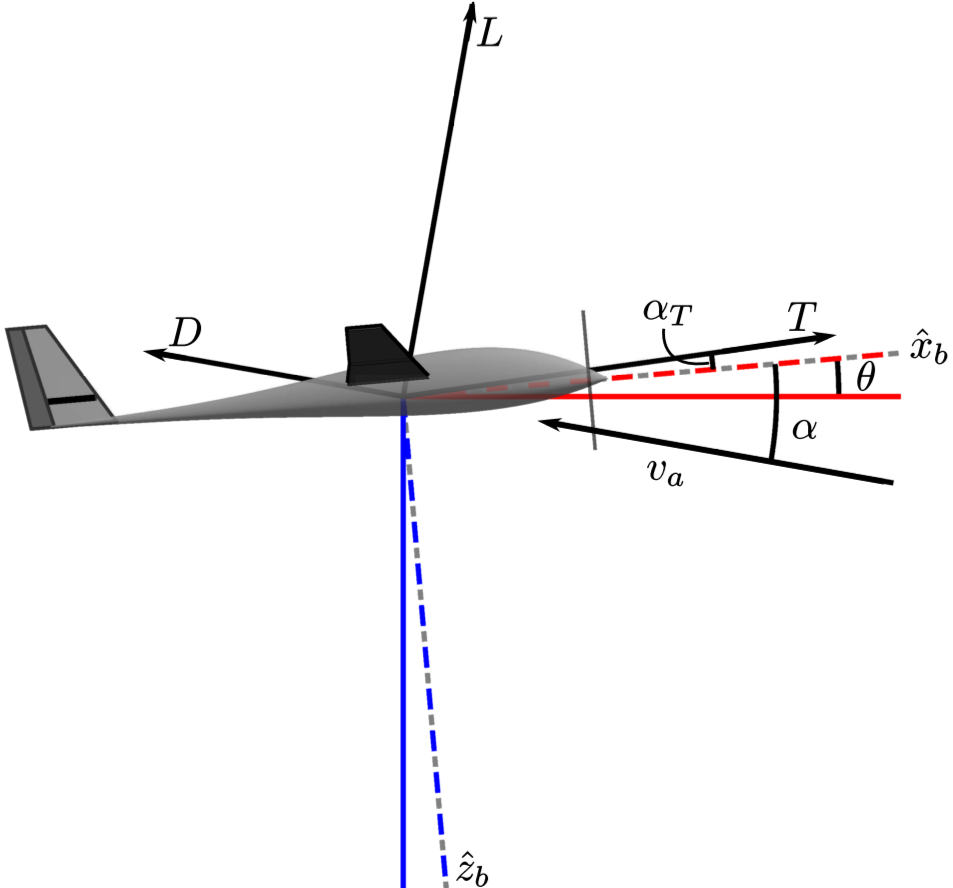

This may be unclear on first sight because a plane operates on all 3-axis. The energy storage of the airplane is only in its height and speed. So every movement of the plane change either the height or the speed of the plane. Because we operate a glider, the speed is mostly dependent on the height. (Speed is generated by height loss) The roll axis has no energy storage. Rolling the plane decrease speed, and so indirectly height. Yawing the plane also decrease speed.

In the following we start calculation the energy.

We start by defining the different energies in our model.    


$$\begin{array}{l}
E_{\textrm{Kin}} =\frac{1}{2}*m*v^2 \\
E_{\textrm{Pot}} =m*g*h\\
E=E_{\textrm{Kin}} +E_{\textrm{Pot}} =\frac{1}{2}*m*v^2 +m*g*h\\
E=m\left\lbrack \frac{1}{2}*v^2 +g*h\right\rbrack \\

\end{array}$$


Now we will make the formula independent of the mass of the plane, so that we get a normalized energy variable.


$$\frac{E}{m}=\frac{1}{2}*v^2 +g*h$$


In this step we set m=1, we get the normalized energy in therms of its weight. (The new unit will be $\frac{m^2 }{s^2 }$)


$$E=\frac{1}{2}*v^2 +g*h$$


Because we already know that the energy is processed on an embedded system, we simplify the calculation. The current problem is mostly the second therm because we get an unnecessary multiplication. 1/2 can be computed in advanced. We try to get the g into the Formula for the kinetic energy.


$$\begin{array}{l}
E=g\left\lbrack \frac{1}{2g}*v^2 +h\right\rbrack \\
\frac{E}{g}=\frac{1}{2g}*v^2 +h
\end{array}$$


Now we can precompute the g into the 1/2. For the E/g we define a new symbol e.


$$e=\frac{E}{g}$$


So we get the final equation of:


$$e=\frac{1}{2g}*v^2 +h\;$$


The specific energy has units of altitude [m]. The first part describes the energy that can be converted to altitude, the second part is the current altitude.

## Simulation

First, we declare some variables

clc;clear;
g = 9.81 % Earth gravity

g = 9.8100

h = 50  %initial height over ground

h = 50

v = 20/3.6 % initial airspeed in m/s (20km/h)

v = 5.5556

q = 0.2 % sinkrate of 0.2 meter per second

q = 0.2000

distancX(1) = 0 % traveled distance in x

distancX = 0

distancY(1) = 0 % traveled distance in y

distancY = 0

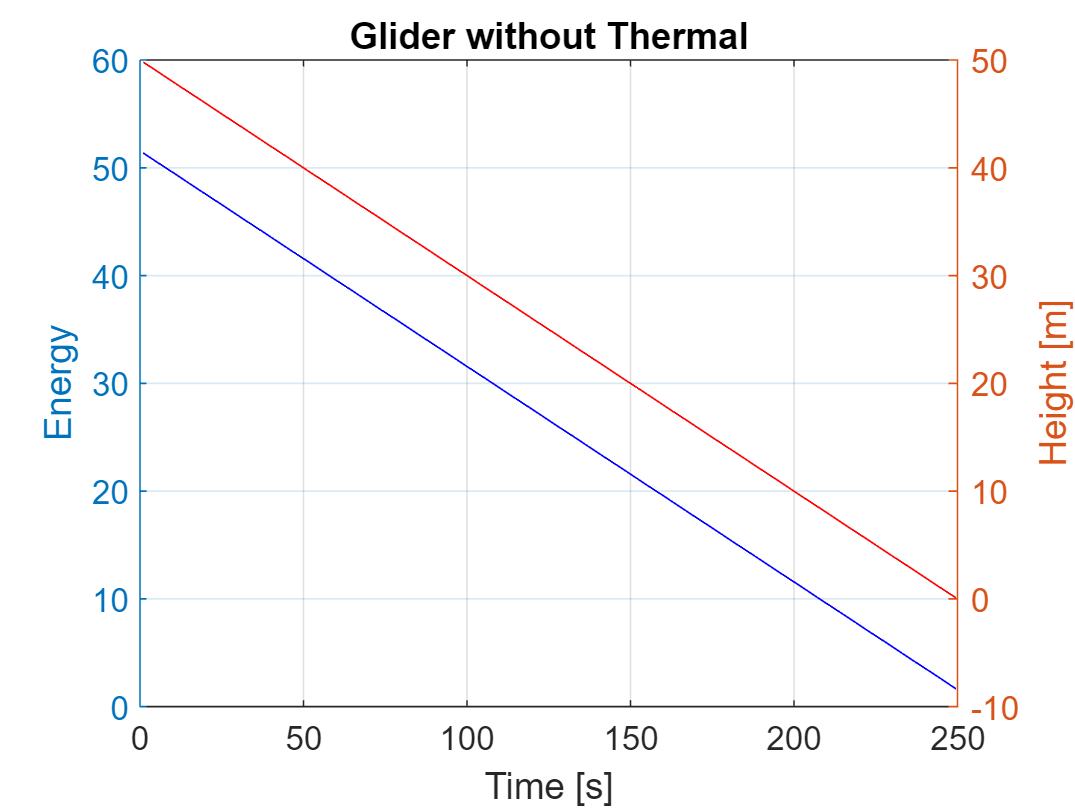



% The calculation timestep is 1 sec

i = 1;
while h > 0
h = h-q;
e = 1/(2*g)*v^2 + h;
E(i) = e; % create an energy array
H(i) = h; % create an height array
time(i) = i; % create an time array
i = i+1;
distancX(i) = distancX(i-1)+v;
distancY(i) = distancY(i-1);
end


% Plot the data
figure(1);clf;
yyaxis left
plot(time, E, 'b-');
ylabel('Energy');
hold on;
yyaxis right
plot(time, H, 'r-')
ylabel('Height [m]');
grid on;
xlabel('Time [s]');
title('Glider without Thermal');
hold off;

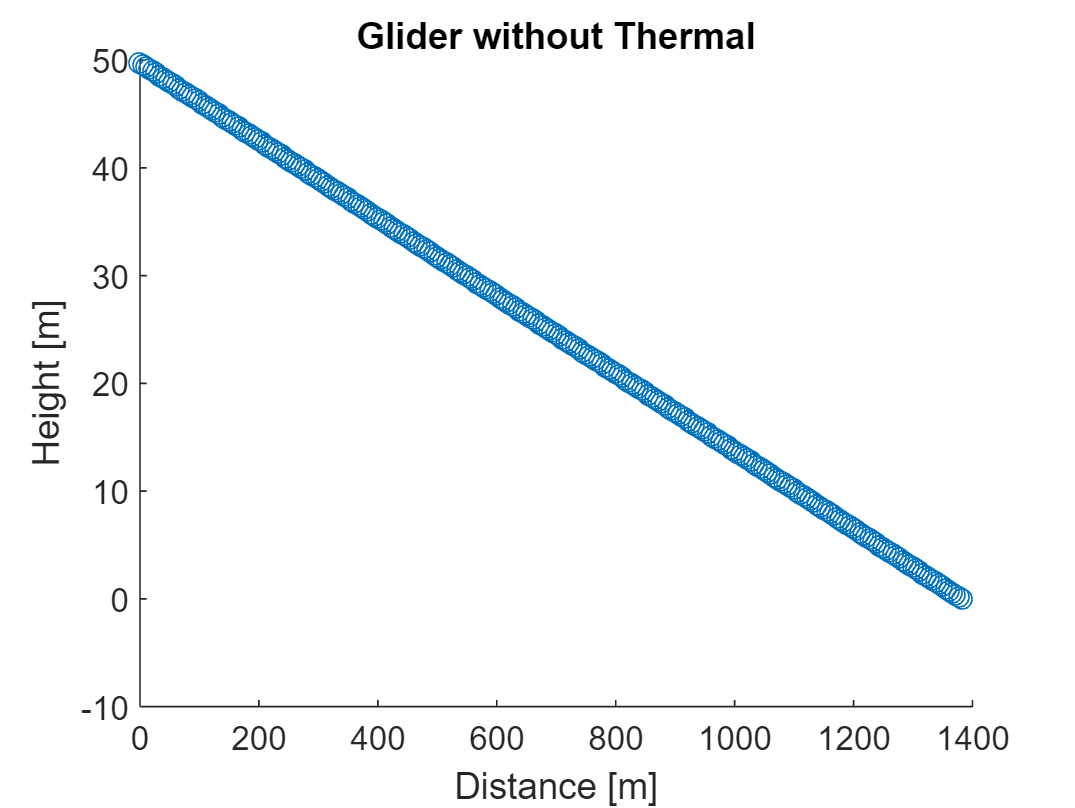


figure(2);clf;
scatter(distancX(1:length(distancX)-1),H)
hold on;
xlabel('Distance [m]');
ylabel('Height [m]');
title('Glider without Thermal');
hold off;

Now we simulate thermals in the flight.

clc; clear;
g = 9.81 % Earth gravity

g = 9.8100

h = 50  %initial height over ground

h = 50

v = 20/3.6 % initial airspeed in m/s (20km/h)

v = 5.5556

q = 0.2 % sinkrate of 0.2 meter per second

q = 0.2000

distancX(1) = 0 % traveled distance in x

distancX = 0

distancY(1) = 0 % traveled distance in y

distancY = 0


s = 1,2 % climbrate in thermal [m/s]

s = 1

ans = 2

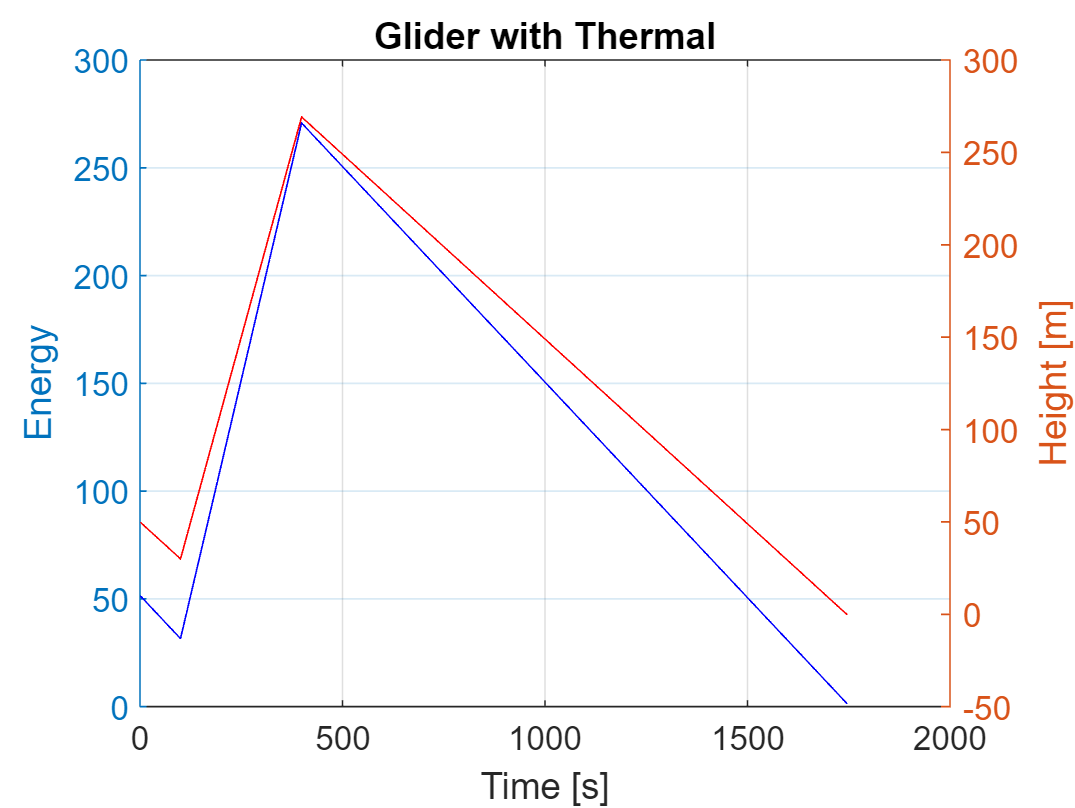




% The calculation timestep is 1 sec
thermal = false;
i = 1;
while h > 0

h = h-q;
if i>100 && i<400 % in here will be simulated thermals 
    h = h+s;
    thermal = true; % set flag that the plane is currently in thermals
else
    thermal = false;
end
e = 1/(2*g)*v^2 + h;
E(i) = e; % create an energy array
H(i) = h; % create an height array
time(i) = i; % create an time array
i = i+1;
if thermal == false % because the plane cyrcles in thermal dont increase distance
    distancX(i) = distancX(i-1)+v;
    distancY(i) = distancY(i-1);
else
    distancX(i) = distancX(i-1);
    distancY(i) = distancY(i-1);
end

end


% Plot the data
figure(3);clf;
yyaxis left
plot(time, E, 'b-');
ylabel('Energy');
hold on;

yyaxis right
plot(time, H, 'r-')
ylabel('Height [m]');

grid on;
xlabel('Time [s]');

title('Glider with Thermal');
hold off;

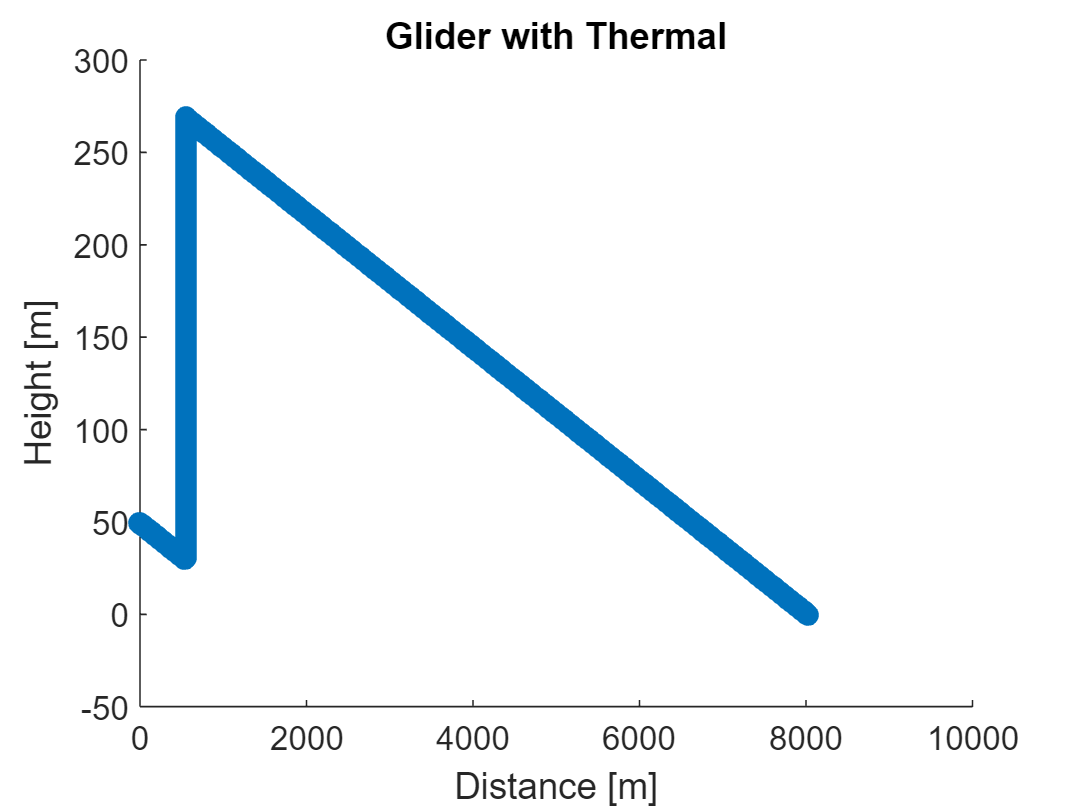


figure(4);clf;
scatter(distancX(1:length(distancX)-1),H)
hold on;
xlabel('Distance [m]');
ylabel('Height [m]');
title('Glider with Thermal');
hold off;

If we want to know if the plane is climbing or not, we use the first derivative.


$$\begin{array}{l}
e=\frac{1}{2g}*v^2 +h\;\\
\dot{e} =\frac{1}{g}*v*\dot{v} +\dot{h} 
\end{array}$$


We can't use the first derivative because we don't know the function of v and h. (We know it after the flight). We use the base definition of the derivative:


$$\frac{\mathrm{d}}{\mathrm{d}t}e\left(t\right)=\frac{\Delta e}{\Delta t}$$


With this formula, we can plot the change in energy.

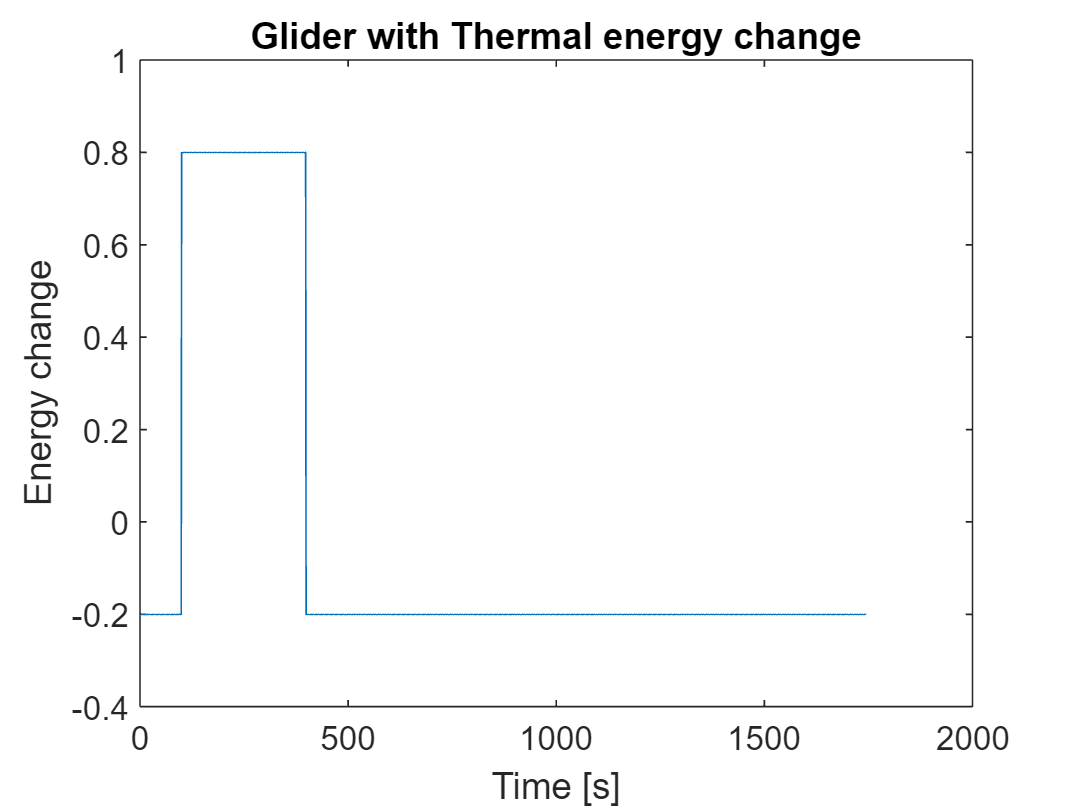

for i = 1:length(E)-1
eDot(i) = (E(i+1)-E(i))/1;
time_dot(i) = i;
end

figure(5);clf;
plot(time_dot,eDot)
ylabel('Energy change');
xlabel('Time [s]');
title('Glider with Thermal energy change');